# ARMA Model Selection

## Exercise 58

This question asks us the apply the model selection techniques from Michaelmas to check which time series model is the "best". Here we will select the best model using information criteria.

We will consider the space of possible models to be anything smaller than an ARMA (4,4).

Let's begin by reloading the data:

load term_premium.mat

One additional input that we require is a holdback for the number of observations. The holdback is the number of observations that we discard for all models in order to make the different models we compare use the same sample. Since the most complete model we will consider has four lags, this holdback (`MAX_AR`) will be four.

% Setting the holdback:
MAX_AR = 4;

Now we loop over the different models:

LLs = zeros(5,5);
AICs = zeros(5,5);
BICs = zeros(5,5);
options.Display = 'none';

for i = 0:4 % AR lags
    for j= 0:4 % MA lags
        disp(['AR: ' num2str(i) ' MA: ' num2str(j)])
        [p,ll,ser] = armaxfilter(tp,1,1:i,1:j,[],[],options,MAX_AR);
        LLs(i+1,j+1) = ll;
        AICs(i+1,j+1) = 2*ll - 2*(1+i+j);
        BICs(i+1,j+1) = 2*ll - log(length(tp)-MAX_AR) * (1+i+j);
    end
end

AR: 0 MA: 0
AR: 0 MA: 1
AR: 0 MA: 2
AR: 0 MA: 3
AR: 0 MA: 4
AR: 1 MA: 0
AR: 1 MA: 1
AR: 1 MA: 2
AR: 1 MA: 3
AR: 1 MA: 4
AR: 2 MA: 0
AR: 2 MA: 1
AR: 2 MA: 2
AR: 2 MA: 3
AR: 2 MA: 4
AR: 3 MA: 0
AR: 3 MA: 1
AR: 3 MA: 2
AR: 3 MA: 3
AR: 3 MA: 4
AR: 4 MA: 0
AR: 4 MA: 1
AR: 4 MA: 2
AR: 4 MA: 3
AR: 4 MA: 4


[AIC_i,AIC_j] = find(AICs==max(max(AICs)));
disp('AIC chooses p and q:')

AIC chooses p and q:


disp([AIC_i - 1 AIC_j - 1]);

     2     1



[BIC_i,BIC_j] = find(BICs==max(max(BICs)));
disp('BIC chooses p and q:')

BIC chooses p and q:


disp([BIC_i - 1 BIC_j - 1])

     1     1



The BIC, due to the larger penalty term, typically selects a smaller model. 

We illustrate the different AICs and BICs using a graph. We throw away the first row of the AIC and BIC matrix, because the AIC and BIC without the first AR(1) term is way too bad and would make the graph look disproportional. 

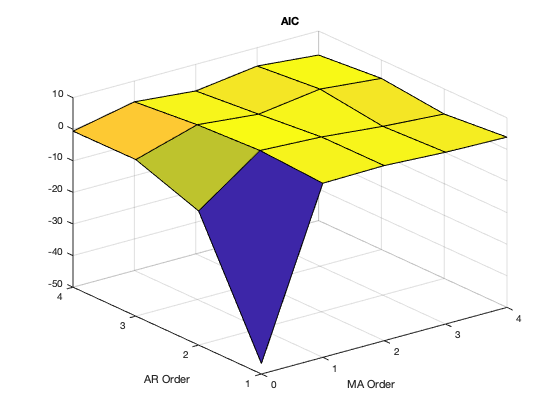

figure()
surf(0:4,1:4,AICs(2:5,:)) % Use surf to produce a surface plot
xlabel('MA Order') % X is the first (columns of data)
ylabel('AR Order') % Y is the second (rows)
title('AIC')

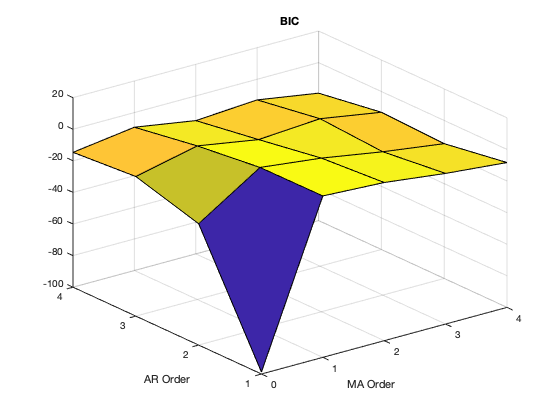

figure()
surf(0:4,1:4,BICs(2:5,:))% Use surf to produce a surface plot
xlabel('MA Order') % X is the first (columns of data)
ylabel('AR Order') % Y is the second (rows)
title('BIC')

It would be a good homework exercise to perform ARMA model selection using general to specific and specific to general methods. You can start with the available code from the chapter on model selection techniques (Exercise 52) and then implement it with `armaxfilter`.